# Blasius Boundary Layer Equation

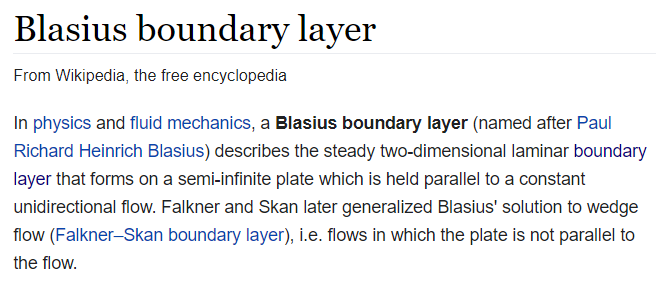

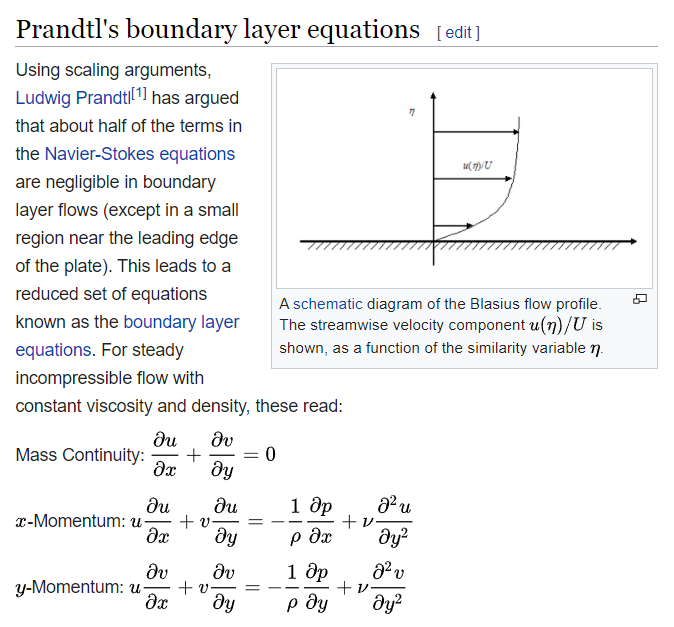

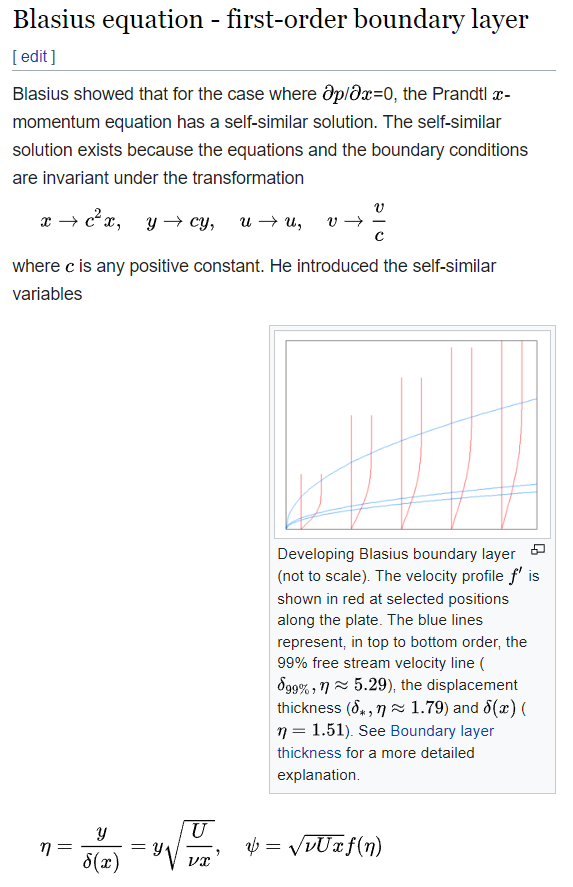

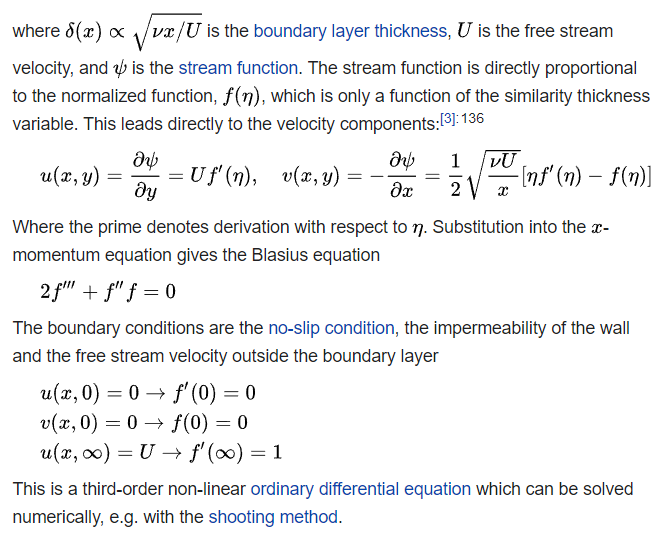

==================================================================================

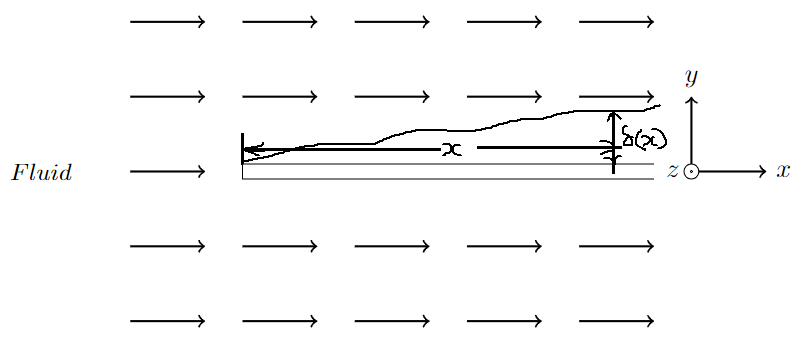$\begin{array}{l}
y_1 =f,y_2 =f^{\prime } ,y_3 ={f^{\prime } }^{\prime } \\
{y_1 }^{\prime } =f^{\prime } =y_2 \\
{y_2 }^{\prime } ={f^{\prime } }^{\prime } =y_3 \\
{y_3 }^{\prime } ={{f^{\prime } }^{\prime } }^{\prime } =-0\ldotp 5{f^{\prime } }^{\prime } f=-0\ldotp 5y_3 y_1 
\end{array}$

ypp = 0.33

ypp = 0.3300

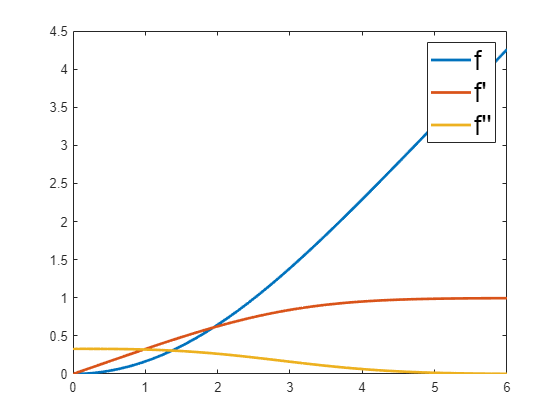

dy = @(t, y)[y(2); y(3); -0.5*y(3)*y(1)];
[T, Y] = ode45(dy, [0, 6], [0, 0, ypp]);
plot(T, Y, 'linewidth', 2);
legend("f","f'", "f''", 'Fontsize', 20);